# Value and Consumption Low vs Higher Discount Factor Comparison

This is the example vignette for function: [**snw_vfi_main_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/svalpol/snw_vfi_main_bisec_vec.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for the V(states) for individuals at lower and higher discount factor $\beta$. We allow for $\beta$ heterogeneity in the model to consider both patient and impatient households. The key difference is that patient households are more willing to save and will consume less.

## Solve Model at $\beta=0.95$

Our high type households have $\beta=0.95$.

% mp_params = snw_mp_param('default_dense');
mp_params = snw_mp_param('default_docdense');
fl_higher_beta = 0.95;
fl_lower_beta = 0.60;
mp_params('beta') = fl_higher_beta;
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_timer') = true;
[V_ss_beta95,~,cons_ss_beta95,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls);

Completed SNW_VFI_MAIN_BISEC_VEC;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=490.4065


## Solve Model at $\beta=0.60$

Our high type households have $\beta=0.60$.

mp_params('beta') = fl_lower_beta;
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_timer') = true;
[V_ss_beta60,~,cons_ss_beta60,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls);

Completed SNW_VFI_MAIN_BISEC_VEC;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=487.891


## Generate $\beta$ Comparison Matrixes

Take the difference between $\beta=0.95$ percent and $\beta=0.60$ consumption and value n-dimensional matrixes. Welfare is converted to units in fixed life-time consumption. Note that for example: $\log(0.5) + 0\cdot\log(0.5) > \log(0.5) +  0.99\cdot\log(0.5)$, in another word, V is higher with lower $\beta$ if utility per-period is a negative value. Note our $\gamma=2$ for the CRRA parameter. We can compare V relatively across choices for the same individual, but less meaningfully across individuals with varying preferences.

gamma = mp_params('gamma');
mn_V_gain_beta = snw_hh_welfare(V_ss_beta95, gamma) - snw_hh_welfare(V_ss_beta60, gamma);
mn_C_gain_beta = cons_ss_beta95 - cons_ss_beta60;
fl_beta_gap = fl_higher_beta - fl_lower_beta;

## Dense Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids: 
age_grid = 18:100;
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Difference in V and C with Higher and Lower $\beta$

The difference between V and C with higher and lower $\beta$.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 21; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

MEAN(MN_V_GAIN(A,Z))

Tabulate value and policies along savings and shocks:

% Set
ar_permute = [1,4,5,6,3,2];
% Value Function
st_title = ['MEAN(MN_V_Gain(A,Z)), beta_gap=' num2str(fl_beta_gap) ];
tb_az_v = ff_summ_nd_array(st_title, mn_V_gain_beta, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_Gain(A,Z)), beta_gap=0.35  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27    mean_e

% Consumption
st_title = ['MEAN(MN_C_Gain(A,Z)), beta_gap=' num2str(fl_beta_gap) ];
tb_az_c = ff_summ_nd_array(st_title, mn_C_gain_beta, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_C_Gain(A,Z)), beta_gap=0.35  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1     mean_eta_2     mean_eta_3     mean_eta_4     mean_eta_5     mean_eta_6     mean_eta_7     mean_eta_8     mean_eta_9     mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27    

Graph Mean Values:

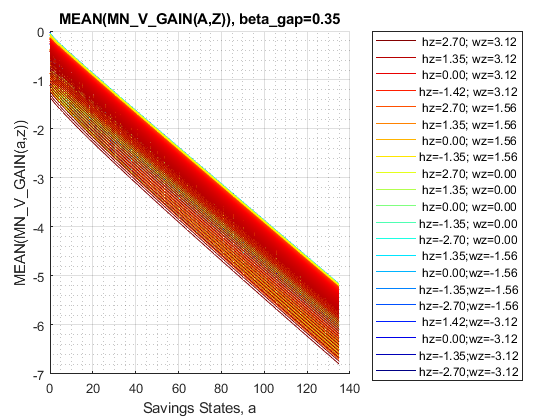

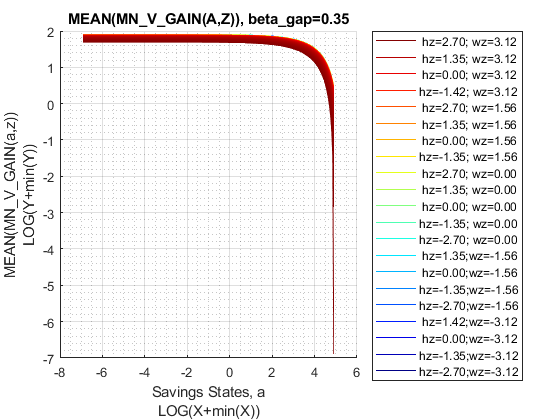

st_title = ['MEAN(MN\_V\_GAIN(A,Z)), beta\_gap=' num2str(fl_beta_gap)  ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_GAIN(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption:

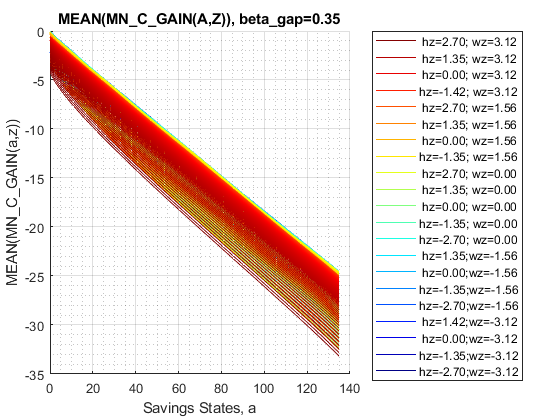

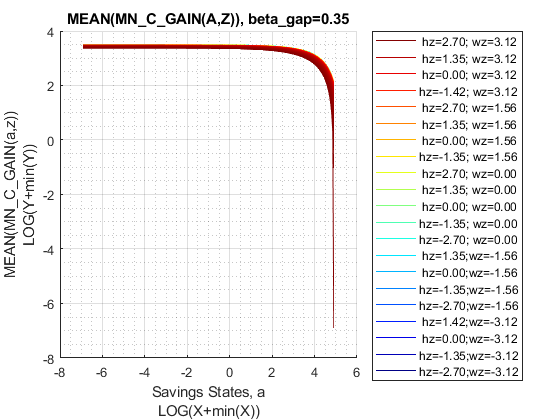

st_title = ['MEAN(MN\_C\_GAIN(A,Z)), beta\_gap=' num2str(fl_beta_gap)  ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_C\_GAIN(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
st_title = ['MEAN(MN_V_Gain(KM,J)), beta_gap=' num2str(fl_beta_gap) ];
tb_az_v = ff_summ_nd_array(st_title, mn_V_gain_beta, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_Gain(KM,J)), beta_gap=0.35  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    mean_age

% Consumption Function
st_title = ['MEAN(MN_C_Gain(KM,J)), beta_gap=' num2str(fl_beta_gap) ];
tb_az_c = ff_summ_nd_array(st_title, mn_C_gain_beta, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_C_Gain(KM,J)), beta_gap=0.35  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    mean_age

Graph Mean Values:

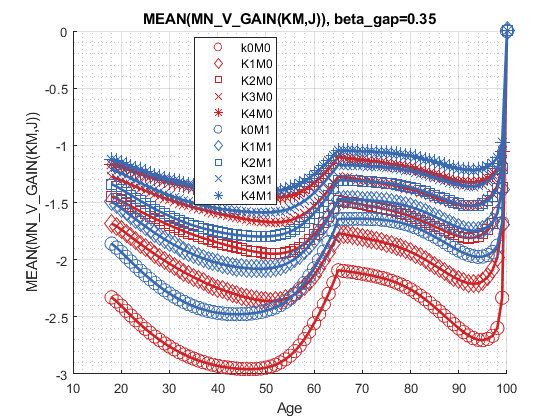

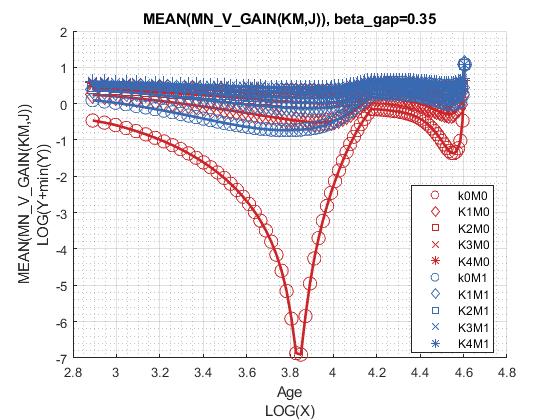

st_title = ['MEAN(MN\_V\_GAIN(KM,J)), beta\_gap=' num2str(fl_beta_gap)  ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_GAIN(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

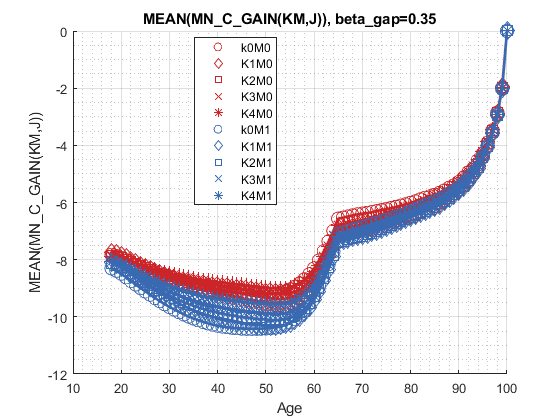

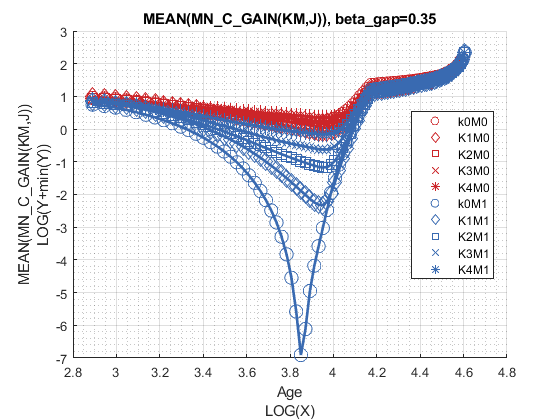

st_title = ['MEAN(MN\_C\_GAIN(KM,J)), beta\_gap=' num2str(fl_beta_gap)  ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_C\_GAIN(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

MEAN(VAL(EM,J)), MEAN(AP(EM,J)), MEAN(C(EM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
st_title = ['MEAN(MN_V_Gain(EM,J)), beta_gap=' num2str(fl_beta_gap) ];
tb_az_v = ff_summ_nd_array(st_title, mn_V_gain_beta, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_Gain(EM,J)), beta_gap=0.35  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    mean_age_

% Consumption
st_title = ['MEAN(MN_C_Gain(EM,J)), beta_gap=' num2str(fl_beta_gap) ];
tb_az_c = ff_summ_nd_array(st_title, mn_C_gain_beta, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_C_Gain(EM,J)), beta_gap=0.35  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43    mean_age_

Graph Mean Values:

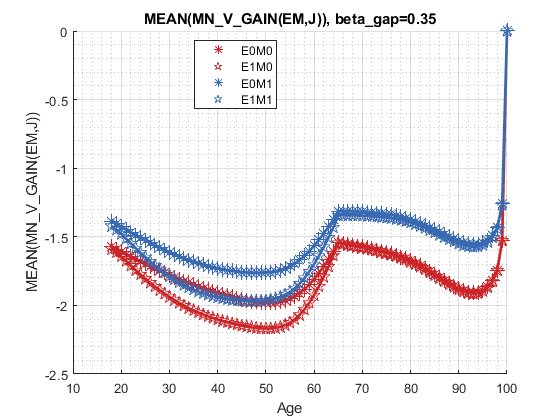

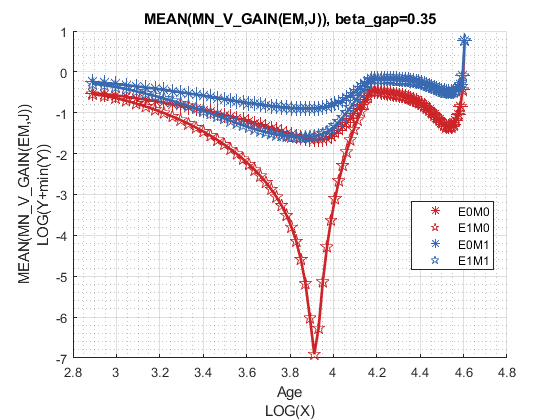

st_title = ['MEAN(MN\_V\_GAIN(EM,J)), beta\_gap=' num2str(fl_beta_gap)  ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_GAIN(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

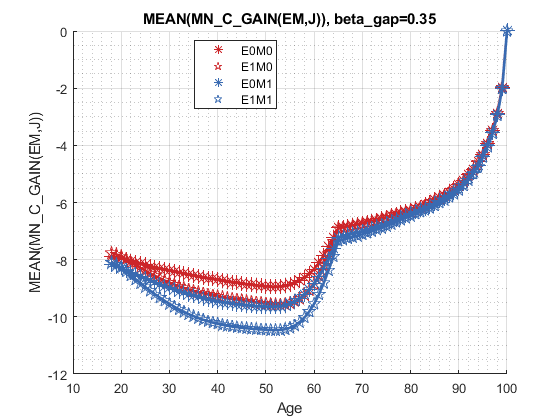

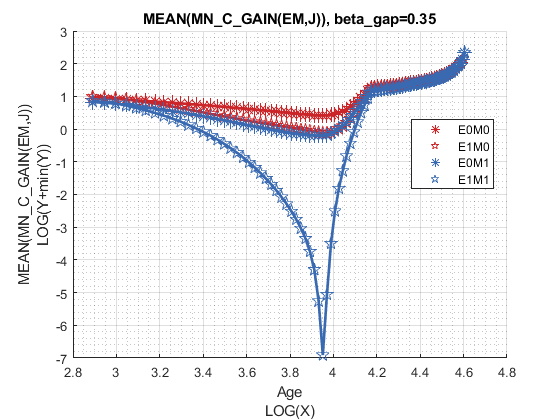

st_title = ['MEAN(MN\_C\_GAIN(EM,J)), beta\_gap=' num2str(fl_beta_gap)  ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_C\_GAIN(EM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);